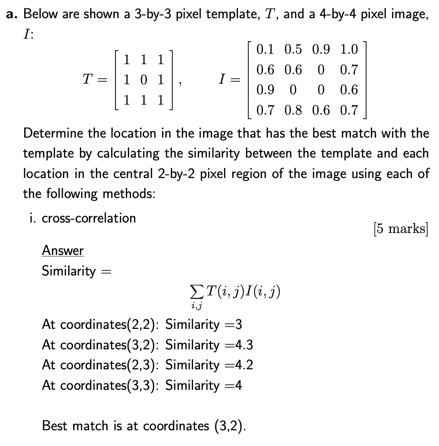

% 2017-2018, p22
T = [1 1 1
     1 0 1
     1 1 1];

T = rot90(T, 90);

I = [0.1 0.5 0.9 1.0
     0.6 0.6 0 0.7
     0.9 0 0 0.6
     0.7 0.8 0.6 0.7];

conv2(I, T, "valid")

ans =     3.0000    4.3000
    4.2000    4.0000


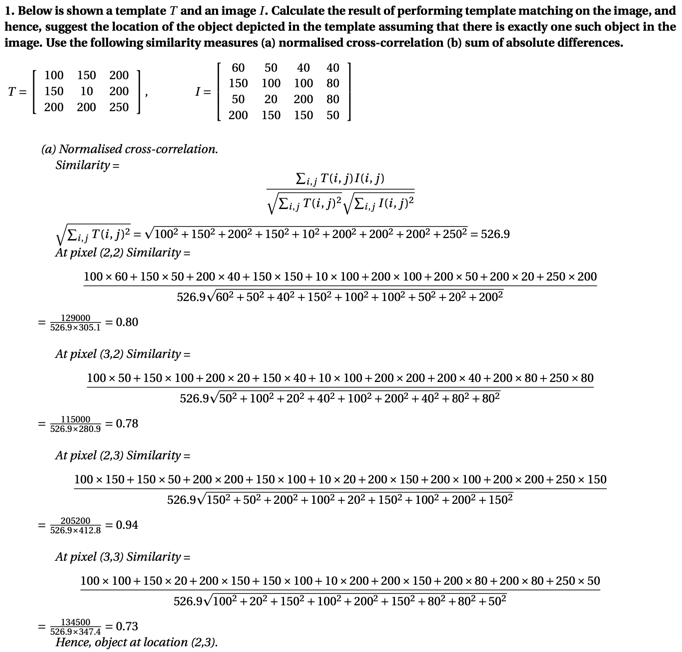

% Normalized cross-correlation
T = [100 150 200
     150 10 200
     200 200 250];

T_180 = rot90(T, 90);

I = [60 50 40 40
     150 100 100 80
     50 20 200 80
     200 150 150 50];

sqrt_sum_T_2 = sqrt(sum_matrix(T.^2));
I_2 = I.^2;

numerators = conv2(I, T_180, "valid");
denominators = zeros(2,2);
for i = 1:2
    for j = 1:2
        denominators(i,j) = sqrt_sum_T_2 * sqrt(sum_matrix(I_2(i:i+2,j:j+2)));
    end
end

numerators ./ denominators % maximum

ans =     0.8024    0.7771
    0.9435    0.7348


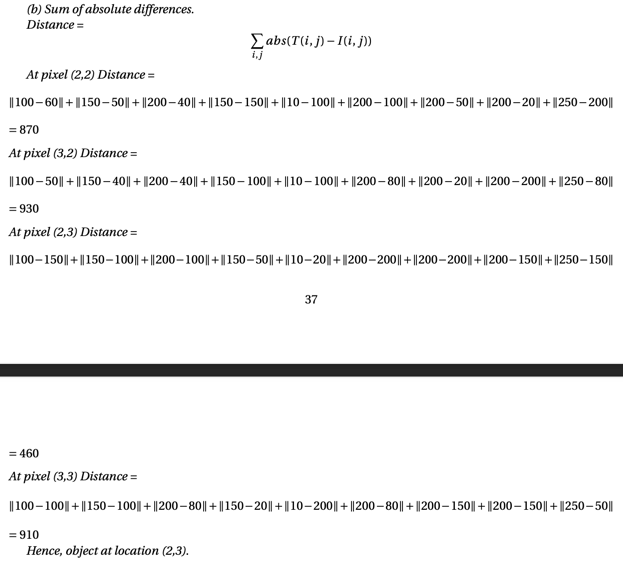

% Sum of absolute difference
pixels = zeros(2,2);
for i = 1:2
    for j = 1:2
        pixels(i,j) = sum_matrix(abs(T - I(i:i+2,j:j+2)));
    end
end

pixels % minimum

pixels =    870   930
   460   910


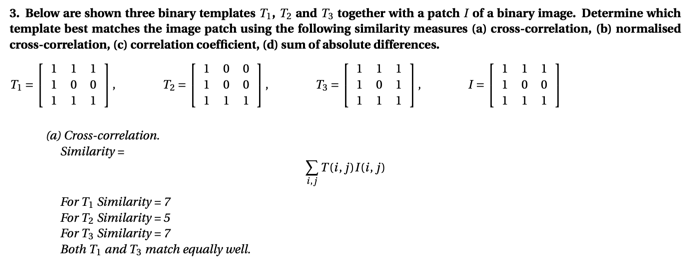

T1 = [1 1 1
      1 0 0
      1 1 1];

T2 = [1 0 0
      1 0 0
      1 1 1];

T3 = [1 1 1
      1 0 1
      1 1 1];

I = [1 1 1
     1 0 0
     1 1 1];

% Maximum
T1_180 = rot90(T1, 90);
T1_numerator = conv2(I,T1_180,"valid")

T1_numerator = 7


T2_180 = rot90(T2, 90);
T2_numerator = conv2(I,T2_180,"valid")

T2_numerator = 5


T3_180 = rot90(T3, 90);
T3_numerator = conv2(I,T3_180,"valid")

T3_numerator = 7

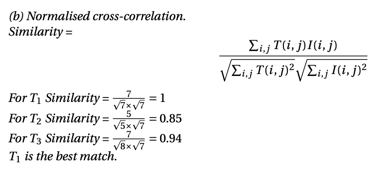

sqrt_sum_T1_2 = sqrt(sum(sum(T1.^2)));
sqrt_sum_T2_2 = sqrt(sum(sum(T2.^2)));
sqrt_sum_T3_2 = sqrt(sum(sum(T3.^2)));
I_2 = I.^2;

% Maximum
T1_numerator / (sqrt_sum_T1_2 * sqrt(sum_matrix(I_2)))

ans = 1.0000

T2_numerator / (sqrt_sum_T2_2 * sqrt(sum_matrix(I_2)))

ans = 0.8452

T3_numerator / (sqrt_sum_T3_2 * sqrt(sum_matrix(I_2)))

ans = 0.9354

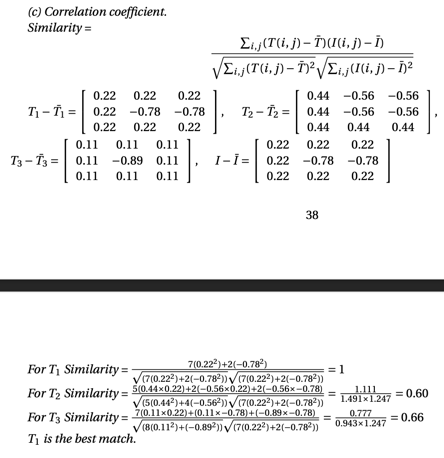

% Maximum
corr2(T1, I)

ans = 1

corr2(T2, I)

ans = 0.5976

corr2(T3, I)

ans = 0.6614

ans = 1.0000

ans = 0.5976

ans = 0.6614

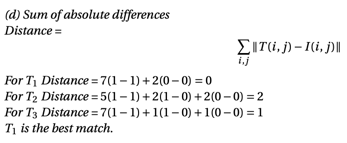

% Minimum
sum_matrix(abs(T1-I))

ans = 0

sum_matrix(abs(T2-I))

ans = 2

sum_matrix(abs(T3-I))

ans = 1

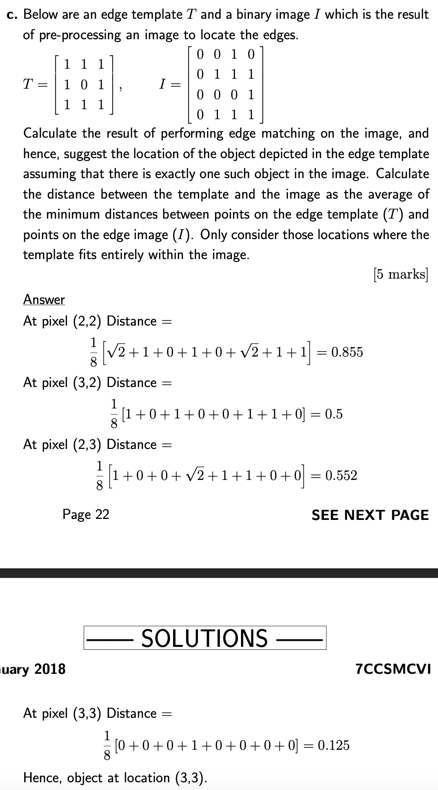

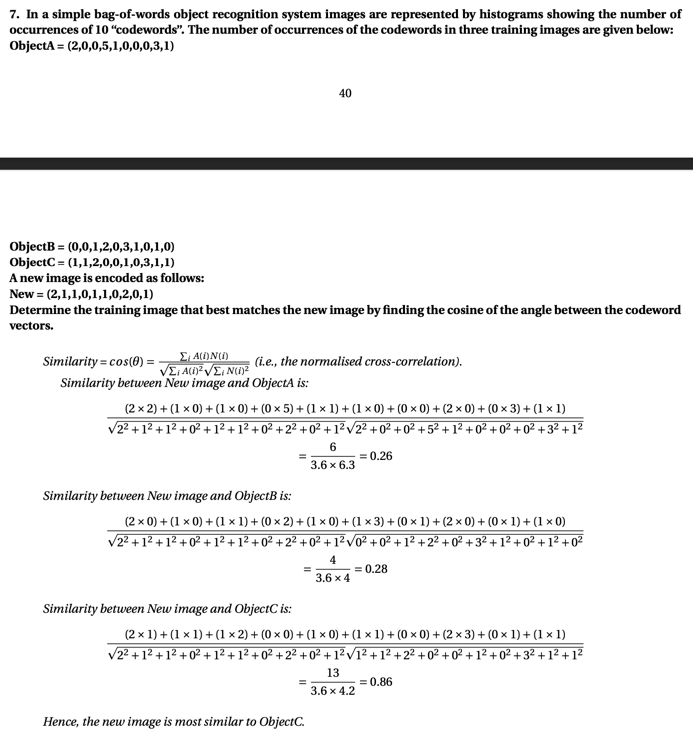

O_A = [2 0 0 5 1 0 0 0 3 1];
O_B = [0 0 1 2 0 3 1 0 1 0];
O_C = [1 1 2 0 0 1 0 3 1 1];
new = [2 1 1 0 1 1 0 2 0 1];

% Miximum
sum(O_A .* new) / (sqrt(sum(O_A.^2)) * sqrt(sum(new.^2)))

ans = 0.2631

sum(O_B .* new) / (sqrt(sum(O_B.^2)) * sqrt(sum(new.^2)))

ans = 0.2774

sum(O_C .* new) / (sqrt(sum(O_C.^2)) * sqrt(sum(new.^2)))

ans = 0.8498

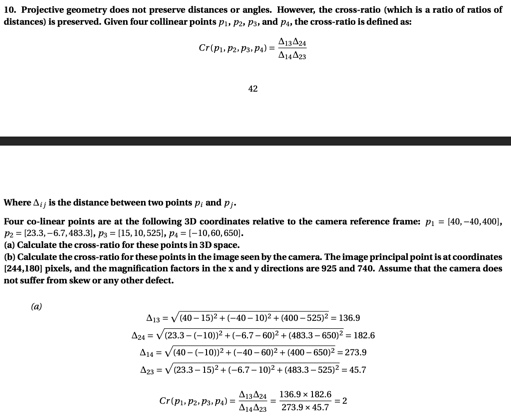

p1 = [40 -40 400];
p2 = [23.3 -6.7 483.3];
p3 = [15 10 525];
p4 = [-10 60 650];

delta_13 = sqrt(sum((p1-p3).^2))

delta_13 = 136.9306

delta_24 = sqrt(sum((p2-p4).^2))

delta_24 = 182.6107

delta_14 = sqrt(sum((p1-p4).^2))

delta_14 = 273.8613

delta_23 = sqrt(sum((p2-p3).^2))

delta_23 = 45.6801

Cr = (delta_13 * delta_24) / (delta_14 * delta_23)

Cr = 1.9988

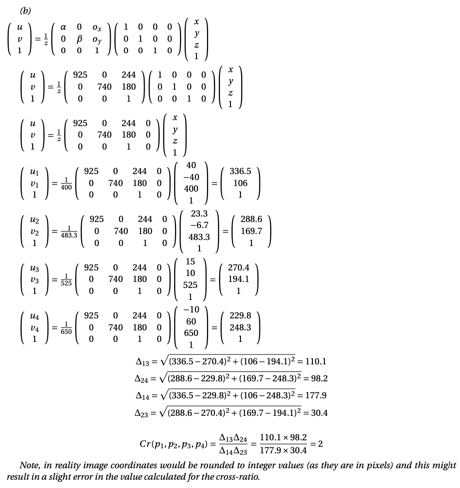

principal_point = [244 180]

principal_point =    244   180


x = 925

x = 925

y = 740

y = 740


p1_img = location_in_img(x,y,principal_point,p1).'

p1_img =   336.5000  106.0000    1.0000


p2_img = location_in_img(x,y,principal_point,p2).'

p2_img =   288.5945  169.7414    1.0000


p3_img = location_in_img(x,y,principal_point,p3).'

p3_img =   270.4286  194.0952    1.0000


p4_img = location_in_img(x,y,principal_point,p4).'

p4_img =   229.7692  248.3077    1.0000



delta_13 = sqrt(sum((p1_img(1:2) - p3_img(1:2)).^2))

delta_13 = 110.1190

delta_24 = sqrt(sum((p2_img(1:2) - p4_img(1:2)).^2))

delta_24 = 98.1482

delta_14 = sqrt(sum((p1_img(1:2) - p4_img(1:2)).^2))

delta_14 = 177.8846

delta_23 = sqrt(sum((p2_img(1:2) - p3_img(1:2)).^2))

delta_23 = 30.3827

Cr = (delta_13 * delta_24) / (delta_14 * delta_23)

Cr = 1.9998

function out = location_in_img(x,y,principal_point,p)
    matrix = [x 0 principal_point(1) 0
              0 y principal_point(2) 0
              0 0 1 0];
    p_T = p.';
    p_T(4) = 1;
    out = 1/p(3) * matrix * p_T;
end

function out = sum_matrix(x)
    out = sum(sum(x));
end